### 4.7

Три однофазных приемника объеденены в звезду и подключены симметричному трехфазному генератору, также соединенному звездой

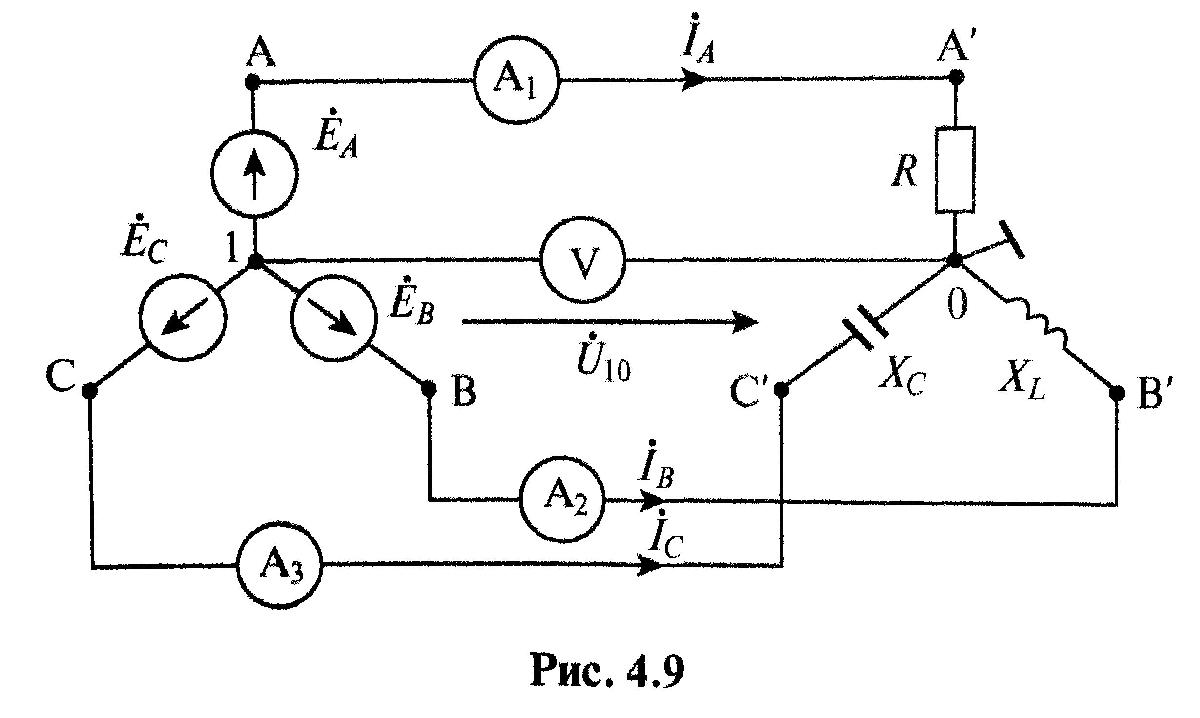

clear
R=55 % Ом

R = 55

X_L=44 % Ом

X_L = 44

X_C=36.6 % Ом

X_C = 36.6000

E_f=220 % В

E_f = 220

Ed_A=220

Ed_A = 220

Ed_B=220*exp(1j*4*pi/3)

Ed_B = -1.1000e+02 - 1.9053e+02i

Ed_C=220*exp(1j*2*pi/3)

Ed_C = -1.1000e+02 + 1.9053e+02i

Z_A=55

Z_A = 55

Z_B=1j*44

Z_B = 0.0000 + 44.0000i

Z_C=-1j*36.6

Z_C = 0.0000 - 36.6000i

1) Применяем метод узловых напряжений

syms Ud_10 Jd_11 Yd_11
syms Ed_A Ed_B Ed_C Yd_A Yd_B Yd_C
Ud_10==Jd_11/Yd_11

$$ans = {\mathrm{Ud}}_{10}=\frac{{\mathrm{Jd}}_{11}}{{\mathrm{Yd}}_{11}}$$

% где
Jd_11==-(Ed_A*Yd_A+Ed_B*Yd_B+Ed_C*Yd_C), Yd_11==(Yd_A+Yd_B+Yd_C)

$$ans = {\mathrm{Jd}}_{11}=-{\mathrm{Ed}}_{A}\,{\mathrm{Yd}}_{A}-{\mathrm{Ed}}_{B}\,{\mathrm{Yd}}_{B}-{\mathrm{Ed}}_{C}\,{\mathrm{Yd}}_{C}$$

$$ans = {\mathrm{Yd}}_{11}={\mathrm{Yd}}_{A}+{\mathrm{Yd}}_{B}+{\mathrm{Yd}}_{C}$$

2) Найдем численные значения указанных величин

Yd_A=1/Z_A, Yd_B=1/Z_B, Yd_C=1/Z_C

Yd_A = 0.0182

Yd_B = 0.0000 - 0.0227i

Yd_C = 0.0000 + 0.0273i

Ed_A=220, Ed_B=220*exp(1j*4*pi/3), Ed_C=220*exp(1j*2*pi/3)

Ed_A = 220

Ed_B = -1.1000e+02 - 1.9053e+02i

Ed_C = -1.1000e+02 + 1.9053e+02i

Ed_A*Yd_A, Ed_B*Yd_B, Ed_C*Yd_C

ans = 4

ans = -4.3301 + 2.5000i

ans = -5.2056 - 3.0055i

Jd_11=-(Ed_A*Yd_A+Ed_B*Yd_B+Ed_C*Yd_C)

Jd_11 = 5.5357 + 0.5055i

Yd_11=Yd_A+Yd_B+Yd_C

Yd_11 = 0.0182 + 0.0046i

3) Находим узловое напряжение

Ud_10=Jd_11/Yd_11

Ud_10 = 2.9279e+02 - 4.6197e+01i

Модуль этого напряжения определяет показание вольтметра V

U_10=abs(Ud_10)

U_10 = 296.4126

4) Определяем токи в линейных проводах

Id_A=Yd_A*(Ed_A+Ud_10), [abs(Id_A) angle(Id_A)*180/pi]

Id_A = 9.3235 - 0.8399i

ans =     9.3612   -5.1479


Id_B=Yd_B*(Ed_B+Ud_10), [abs(Id_B) angle(Id_B)*180/pi]

Id_B = -5.3801 - 4.1543i

ans =     6.7973 -142.3257


Id_C=Yd_C*(Ed_C+Ud_10), [abs(Id_C) angle(Id_C)*180/pi]

Id_C = -3.9434 + 4.9943i

ans =     6.3634  128.2941


5) Показания амперметров, включенные в линейные провода цепи

A1=abs(Id_A), A2=abs(Id_B), A3=abs(Id_C)

A1 = 9.3612

A2 = 6.7973

A3 = 6.3634

Комплексный ток в точке 0

Id_00=Id_A+Id_B+Id_C  % =0

Id_00 = 1.3323e-15